# Automatic Orbital Landing

You are part of a European launch provider specializing in high-frequency transports between the moon surface and an orbital station. 

As part of your service, your company has established a fledgling moon base which includes a landing/launch tower. While the algorithm to decelerate the rocket out of orbit towards the launch site is already complete, the final landing burn sequency has not yet been designed. 

### Your prototype rocket: Halogen I

The prototype lander "Halogen I" is a small vehicle with a weight of 50kg. It possesses a 150N liquid combustion engine with a TVC (thrust-vector control) rig to angle the engine assembly.

#### Control Inputs:

- $T$: Thrust generated by the engine [0 - 150N]

- $\varphi \;$: TVC orientation of the engine

#### Observable Outputs:

The landing zone is equipped with a long-range motion capture system, which together with the sensors on the rocket, give you access to the following measurements:

- $x$: Horizontal position of the rocket (meters)

- $y$: Altitude of the rocket (meters)

- $\theta \;$: Angle of the rocket (radians)

#### Goal:

The goal is to land the rocket into the clamps of the launch tower (green) with a final velocity lower than 0.3 m/s2. 

## I: Manual Control

Your zealous coworker is convinced with a joystick and a bit of practice he can reliably land the rocket himself. 

Let us have a look at the (simplified) non-linear dynamics of the rocket:


$$m\ddot{x} =T\cdot \sin \left(\theta +\varphi \right)$$



$$m\ddot{y} =T\cdot \cos \left(\theta +\varphi \right)+m\cdot g$$



$$I\ddot{\theta} =T\cdot \sin \left(\varphi \right)\cdot l_1$$


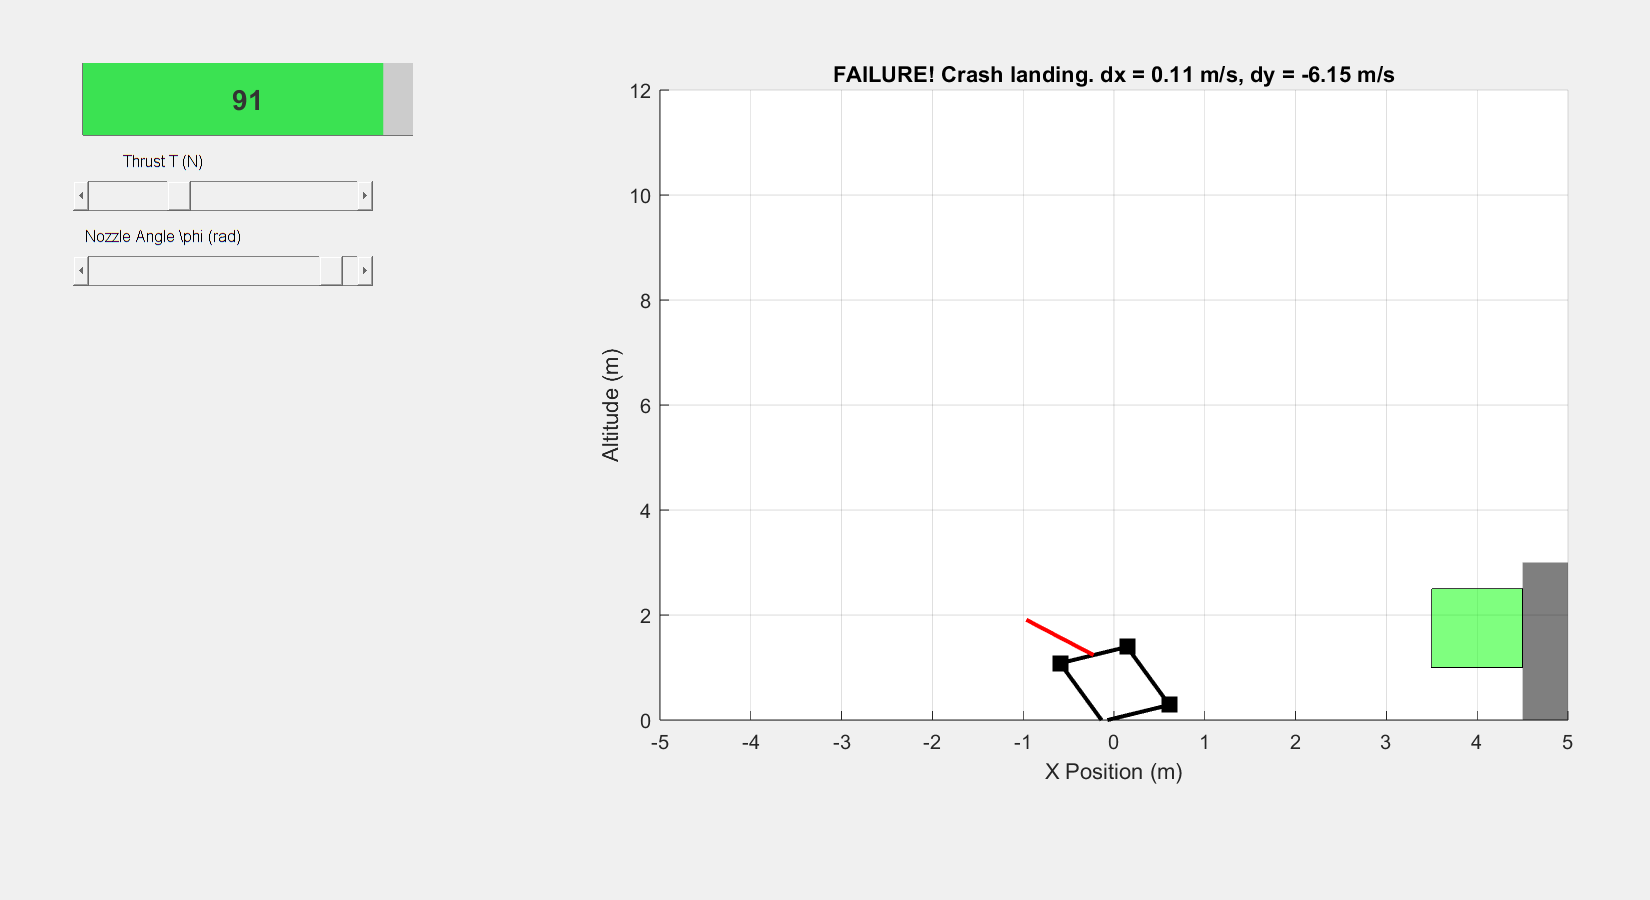

clear; clc; close all;

%% System parameters
m    = 50;        % kg
I    = 2.5;       % kg*m^2
g    = 1.62;      % m/s^2
l1   = 0.5;       % m
T_max= 150;       % N

%% Simulation parameters
dt     = 0.05;
T_total= 100;
time   = 0:dt:T_total;

%% Initial conditions
% True state: [x; dx; y; dy; theta; dtheta]
x_true = zeros(6,1);
x_true(1) = rand(1, 1);
x_true(2) = rand(1, 1);
x_true(3) = 12;   % Initial altitude = 12 m
x_true(4) = -1 + rand(1, 1);   % Initial vertical velocity
x_true(5) = -x_true(2)/3;

%% Define Landing Zones
% Safe landing zone (green square): from x=3 to 4, y=0 to 1.
safe_zone.x = 3.5;
safe_zone.y = 1;
safe_zone.width = 1;
safe_zone.height = 1.5;

% Hazard zone (black tower): to the right of safe zone, e.g., x=4 to 4.5, y=0 to 3.
hazard_zone.x = safe_zone.x + safe_zone.width; % starting at x = 4
hazard_zone.y = 0;
hazard_zone.width = 0.5;
hazard_zone.height = 3;

%% Setup figure, sliders, and plot handles
f = figure('Name', 'Lander Simulation with Manual Control',...
    'NumberTitle','off','Position',[100 100 1100 600]);

% Add score bar background (axes coordinates: [x y width height])
score_bar_bg = axes('Parent', f, 'Position', [0.05 0.85 0.2 0.08], 'XTick', [], 'YTick', [], 'Color', [0.9 0.9 0.9]);
xlim(score_bar_bg, [0 100]);
ylim(score_bar_bg, [0 1]);
rectangle(score_bar_bg, 'Position', [0 0 100 1], 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');

% Add dynamic score bar (green to red gradient)
score_bar = patch(score_bar_bg, [0 100 100 0], [0 0 1 1], [0.2 0.8 0.2],...
    'EdgeColor', 'none', 'FaceAlpha', 0.8);

% Add score text overlay
score_text = text(score_bar_bg, 50, 0.5, '100',...
    'HorizontalAlignment', 'center', 'FontSize', 14,...
    'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);

% Add score label
text(score_bar_bg, 3000, 1.1, 'SCORE',...
    'HorizontalAlignment', 'center', 'FontSize', 10,...
    'FontWeight', 'bold', 'Color', [0.4 0.4 0.4]);

% Thrust slider
uicontrol('Style','text','Position',[50 480 120 20],'String','Thrust T (N)');
thrust_slider = uicontrol('Style','slider',...
    'Min',0,'Max',T_max,'Value',m*g,...  % Hover thrust = m*g
    'Position',[50 460 200 20]);

% Nozzle angle slider
uicontrol('Style','text','Position',[50 430 120 20],'String','Nozzle Angle \phi (rad)');
phi_slider = uicontrol('Style','slider','Min',-0.5,'Max',0.5,'Value',0,...
    'Position',[50 410 200 20]);

% Plot setup
ax = axes('Position',[0.4,0.2,0.55,0.7]);
hold on; grid on;
xlabel('X Position (m)');
ylabel('Altitude (m)');
xlim([-5 5]); ylim([0 12]);
title('Lander Trajectory');

% Create plot handles for lander bodies, nozzles, and reference marker
h_true        = plot(0,0, 'ks-', 'LineWidth',2, 'MarkerSize',8, 'MarkerFaceColor','k');
h_nozzle_true = plot(0,0, 'r-', 'LineWidth',2);

% Draw the safe landing zone (green square)
safe_x = [safe_zone.x, safe_zone.x+safe_zone.width, safe_zone.x+safe_zone.width, safe_zone.x];
x_target = safe_zone.x + safe_zone.width/2 - 0.15;
safe_y = [safe_zone.y, safe_zone.y, safe_zone.y+safe_zone.height, safe_zone.y+safe_zone.height];
y_target = safe_zone.y + safe_zone.height/2;
h_safe = patch(safe_x, safe_y, 'g', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Draw the hazard zone (black tower)
hazard_x = [hazard_zone.x, hazard_zone.x+hazard_zone.width, hazard_zone.x+hazard_zone.width, hazard_zone.x];
hazard_y = [hazard_zone.y, hazard_zone.y, hazard_zone.y+hazard_zone.height, hazard_zone.y+hazard_zone.height];
h_hazard = patch(hazard_x, hazard_y, 'k', 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Define lander and nozzle dimensions (for drawing)
lander_dims.lander_width = 0.8;   % meters
lander_dims.lander_height = 1.2;  % meters
lander_dims.nozzle_length = 1.0;  % meters

% Simulation loop with real-time interaction
k = 1;
while ishandle(f) && k <= length(time)
    % Get manual control inputs from sliders
    T_slider = get(thrust_slider, 'Value');
    phi = get(phi_slider, 'Value');
    u = [T_slider; phi];
    
    % Update state using Euler integration
    x_true = updateTrueState(x_true, u, dt, m, I, g, l1);

    nozzle_command = u(2);
    [lander_x_true, lander_y_true, nozzle_x_true, nozzle_y_true] = computeLanderShape(x_true, lander_dims, nozzle_command);
    
    set(h_true, 'XData', lander_x_true, 'YData', lander_y_true);
    set(h_nozzle_true, 'XData', nozzle_x_true, 'YData', nozzle_y_true);
    
    [landed, success, vel] = checkLanding(x_true, lander_dims, safe_zone, hazard_zone);
    if landed
        if success
            result_str = sprintf('SUCCESS! Landed on safe zone. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        else
            result_str = sprintf('FAILURE! Crash landing. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        end
        title(ax, result_str);
        break;  % End simulation loop upon landing
    else
        % Update title with ongoing state info
        title(ax, sprintf('Altitude: True = %.2f m | Theta: True = %.2f rad',...
            x_true(3), x_true(5)));
    end

    % Update score bar and text
    current_score = max(0, 100 - floor((k-1)*dt));
    score_ratio = current_score/100;
    
    % Update bar color (green to red gradient)
    set(score_bar,...
        'XData', [0 current_score current_score 0],...
        'FaceColor', [1-score_ratio, score_ratio, 0.2]);
    
    % Update text
    set(score_text, 'String', num2str(current_score));
    
    % Flash red when below 100
    if current_score < 10
        set(score_bar, 'FaceColor', [1 0 0]);
    end

    drawnow;
    pause(dt);
    k = k + 1;
end



if landed
    if success
        disp('Landing SUCCESS!');
    else
        disp('Landing FAILURE!');
    end
    fprintf('Final velocities: dx = %.2f m/s, dy = %.2f m/s\n', vel(1), vel(2));
else
    disp('Simulation ended without landing.');
end

Landing FAILURE!


Final velocities: dx = 0.11 m/s, dy = -6.15 m/s


## II: Observer

Seems pretty difficult right? What would make this task probably more challenging in real application is:

- Finite sampling frequency of the sensors

- Sensor noise

Let us construct an observer model using **LQE** to recreate the state $\hat{x}$ using only $y_{\mathrm{meas}}$.


$$\dot{\hat{x} } =A\hat{x} +Bu+L\cdot \left(y_{\mathrm{meas}} -C\hat{x} \right)$$


Note that LQE requires a linear model. We linearize about the equilibrium point $x=0_{6\mathrm{x1}}$ and get the following state-space matrices:

%% Linearized state-space matrices for observer
% State: [x; dx; y; dy; theta; dtheta]
A = [0, 1, 0, 0, 0, 0;
     0, 0, 0, 0, g, 0;
     0, 0, 0, 1, 0, 0;
     0, 0, 0, 0, 0, 0;
     0, 0, 0, 0, 0, 1;
     0, 0, 0, 0, 0, 0];
B = [0, 0;
     0, g;
     0, 0;
     1/m, 0;
     0, 0;
     0, m*g*l1/I];
% Modified C: Now we measure x, y and theta.
C = [1, 0, 0, 0, 0, 0;
     0, 0, 1, 0, 0, 0;
     0, 0, 0, 0, 1, 0];

%% Noise covariances for LQE
Q     = diag([0.1, 0.1, 0.1, 0.1, 0.01, 0.01]); % Process noise covariance
R_cov = diag([0.5, 0.5, 0.05]);                 % Measurement noise covariance
G     = eye(6);  % Assume identity process noise input

% Compute observer gain L using LQE (Kalman filter gain for continuous-time systems)
[L_obs, P, E] = lqe(A, G, C, Q, R_cov);

Try to land the rocket now:

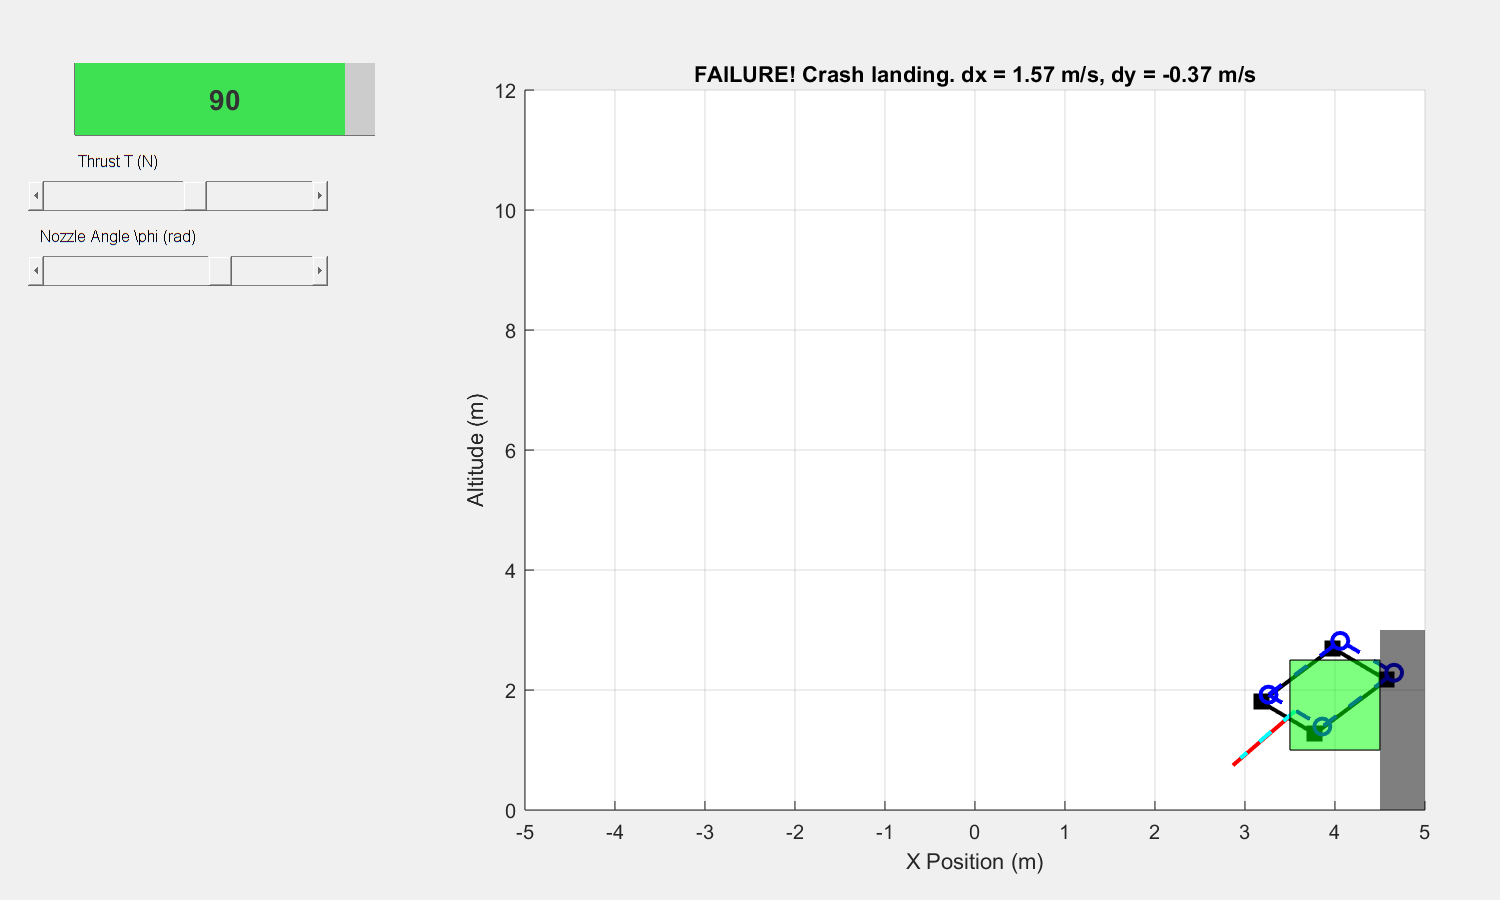

x_true = zeros(6,1);
x_true(3) = 10;   % Altitude = 10 m

% Observer initial estimate
x_hat = zeros(6,1);
x_hat(3) = 10;

%% Setup figure, sliders, and plot handles
f = figure('Name', 'Lander Simulation with Observer','NumberTitle','off','Position',[100 100 1000 600]);

% Add score bar background (axes coordinates: [x y width height])
score_bar_bg = axes('Parent', f, 'Position', [0.05 0.85 0.2 0.08], 'XTick', [], 'YTick', [], 'Color', [0.9 0.9 0.9]);
xlim(score_bar_bg, [0 100]);
ylim(score_bar_bg, [0 1]);
rectangle(score_bar_bg, 'Position', [0 0 100 1], 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');

% Add dynamic score bar (green to red gradient)
score_bar = patch(score_bar_bg, [0 100 100 0], [0 0 1 1], [0.2 0.8 0.2],...
    'EdgeColor', 'none', 'FaceAlpha', 0.8);

% Add score text overlay
score_text = text(score_bar_bg, 50, 0.5, '100',...
    'HorizontalAlignment', 'center', 'FontSize', 14,...
    'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);

% Add score label
text(score_bar_bg, 3000, 1.1, 'SCORE',...
    'HorizontalAlignment', 'center', 'FontSize', 10,...
    'FontWeight', 'bold', 'Color', [0.4 0.4 0.4]);

% Thrust slider
uicontrol('Style','text','Position',[20 480 120 20],'String','Thrust T (N)');
thrust_slider = uicontrol('Style','slider','Min',0,'Max',T_max,'Value',m*g,...
    'Position',[20 460 200 20]);

% Nozzle angle slider
uicontrol('Style','text','Position',[20 430 120 20],'String','Nozzle Angle \phi (rad)');
phi_slider = uicontrol('Style','slider','Min',-0.2,'Max',0.2,'Value',0,...
    'Position',[20 410 200 20]);

% Axes for the 2D plot
ax = axes('Position',[0.35 0.1 0.6 0.8]);
hold on; grid on;
xlabel('X Position (m)');
ylabel('Altitude (m)');
xlim([-5 5]); ylim([0 12]);
title('Lander: True state (black) vs Estimated state (blue)');

% Create plot handles for true and estimated landers and their nozzles
h_true        = plot(0,0, 'ks-', 'LineWidth',2, 'MarkerSize',8, 'MarkerFaceColor','k');
h_nozzle_true = plot(0,0, 'r-', 'LineWidth',2);
h_est         = plot(0,0, 'bo--', 'LineWidth',2, 'MarkerSize',8);
h_nozzle_est  = plot(0,0, 'c--', 'LineWidth',2);

% Draw the safe landing zone (green square)
safe_x = [safe_zone.x, safe_zone.x+safe_zone.width, safe_zone.x+safe_zone.width, safe_zone.x];
x_target = safe_zone.x + safe_zone.width/2 - 0.15;
safe_y = [safe_zone.y, safe_zone.y, safe_zone.y+safe_zone.height, safe_zone.y+safe_zone.height];
y_target = safe_zone.y + safe_zone.height/2;
h_safe = patch(safe_x, safe_y, 'g', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Draw the hazard zone (black tower)
hazard_x = [hazard_zone.x, hazard_zone.x+hazard_zone.width, hazard_zone.x+hazard_zone.width, hazard_zone.x];
hazard_y = [hazard_zone.y, hazard_zone.y, hazard_zone.y+hazard_zone.height, hazard_zone.y+hazard_zone.height];
h_hazard = patch(hazard_x, hazard_y, 'k', 'FaceAlpha', 0.5, 'EdgeColor', 'none');

%% Simulation loop
k = 1;
while ishandle(f) && k <= length(time)
    % Get control inputs from sliders
    T_slider = get(thrust_slider, 'Value');
    phi      = get(phi_slider, 'Value');  % Nozzle deflection (rad)

    u = [T_slider; phi];
    
    % Update true state using the nonlinear dynamics (Euler integration)
    x_true = updateTrueState(x_true, u, dt, m, I, g, l1);
    
    % Simulate measurement (here we assume no noise, but noise can be added)
    noise_level = [0.05; 0.05; 0.01];  % Noise standard deviation for x, y, theta
    y_meas = C * x_true + noise_level .* randn(3, 1);
    
    % Update observer (Luenberger observer) using the linearized model
    x_hat = updateObserver(x_hat, u, y_meas, dt, A, B, C, L_obs);
    
    % Compute the lander shapes for both the true and estimated states.
    [lander_x_true, lander_y_true, nozzle_x_true, nozzle_y_true] = computeLanderShape(x_true, lander_dims, phi);
    [lander_x_est,  lander_y_est,  nozzle_x_est,  nozzle_y_est]  = computeLanderShape(x_hat,  lander_dims, phi);
    
    % Update plot handles for the true state
    set(h_true, 'XData', lander_x_true, 'YData', lander_y_true);
    set(h_nozzle_true, 'XData', nozzle_x_true, 'YData', nozzle_y_true);
    
    % Update plot handles for the estimated state
    set(h_est, 'XData', lander_x_est, 'YData', lander_y_est);
    set(h_nozzle_est, 'XData', nozzle_x_est, 'YData', nozzle_y_est);
    
    % Update title with current altitude and orientation for true vs estimated
    title(ax, sprintf('Altitude: True = %.2f m, Est = %.2f m | Theta: True = %.2f rad, Est = %.2f rad',...
        x_true(3), x_hat(3), x_true(5), x_hat(5)));

    [landed, success, vel] = checkLanding(x_true, lander_dims, safe_zone, hazard_zone);
    if landed
        if success
            result_str = sprintf('SUCCESS! Landed on safe zone. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        else
            result_str = sprintf('FAILURE! Crash landing. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        end
        title(ax, result_str);
        break;  % End simulation loop upon landing
    else
        % Update title with ongoing state info
        title(ax, sprintf('Altitude: True = %.2f m, Est = %.2f m | Theta: True = %.2f rad, Est = %.2f m',...
            x_true(3), x_hat(3), x_true(5), x_hat(5)));
    end

    % Update score bar and text
    current_score = max(0, 100 - floor((k-1)*dt));
    score_ratio = current_score/100;
    
    % Update bar color (green to red gradient)
    set(score_bar,...
        'XData', [0 current_score current_score 0],...
        'FaceColor', [1-score_ratio, score_ratio, 0.2]);
    
    % Update text
    set(score_text, 'String', num2str(current_score));
    
    % Flash red when below 100
    if current_score < 10
        set(score_bar, 'FaceColor', [1 0 0]);
    end
    
    drawnow;
    pause(dt);
    k = k+1;
end


if landed
    if success
        disp('Landing SUCCESS!');
    else
        disp('Landing FAILURE!');
    end
    fprintf('Final velocities: dx = %.2f m/s, dy = %.2f m/s\n', vel(1), vel(2));
else
    disp('Simulation ended without landing.');
end

Landing FAILURE!


Final velocities: dx = 1.57 m/s, dy = -0.37 m/s


## III: LQG

Turns out this is pretty difficult! Let us build an LQR controller to stabilize the rocket to follow a reference position. 

We have an advantage of having used **LQE **earlier. This means we have an estimate of all 6 states, instead of "just" the 3 measurements. Hopefully this will make our LQR more powerful.

%% LQR Controller Design for Tracking
% Augmented cost matrices for the 6-state system
Q_lqr = diag([10, 0.1, 10, 0.1, 10, 0.1]);
R_lqr = diag([0.1, 0.1]);
% Compute LQR gain K (designed on the linearized model)
[K_lqr, S, E_lqr] = lqr(A, B, Q_lqr, R_lqr);

% Equilibrium input (hover): T_eq = m*g, phi_eq = 0.
u_eq = [m*g; 0];

Implementing the controller in code:

x_true = zeros(6,1);
x_true(1) = rand(1, 1);
x_true(2) = rand(1, 1);
x_true(3) = 12;   % Initial altitude = 12 m
x_true(4) = -1 + rand(1, 1);   % Initial vertical velocity
x_true(5) = -x_true(2)/3;

x_hat = x_true;

%% Setup figure, sliders, and plot handles
f = figure('Name', 'Lander Simulation with Observer','NumberTitle','off','Position',[100 100 1000 600]);

score_bar_bg = axes('Parent', f, 'Position', [0.05 0.85 0.2 0.08], 'XTick', [], 'YTick', [], 'Color', [0.9 0.9 0.9]);
xlim(score_bar_bg, [0 100]);
ylim(score_bar_bg, [0 1]);
rectangle(score_bar_bg, 'Position', [0 0 100 1], 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');

% Add dynamic score bar (green to red gradient)
score_bar = patch(score_bar_bg, [0 100 100 0], [0 0 1 1], [0.2 0.8 0.2],...
    'EdgeColor', 'none', 'FaceAlpha', 0.8);

% Add score text overlay
score_text = text(score_bar_bg, 50, 0.5, '100',...
    'HorizontalAlignment', 'center', 'FontSize', 14,...
    'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);

% Add score label
text(score_bar_bg, 3000, 1.1, 'SCORE',...
    'HorizontalAlignment', 'center', 'FontSize', 10,...
    'FontWeight', 'bold', 'Color', [0.4 0.4 0.4]);

% Create reference sliders
uicontrol('Style','text','Position',[20 480 140 20],'String','Reference x (m)');
r_x_slider = uicontrol('Style','slider','Min',-5,'Max',5,'Value',0,...
    'Position',[20 460 200 20]);
uicontrol('Style','text','Position',[20 430 140 20],'String','Reference Altitude r_y (m)');
r_y_slider = uicontrol('Style','slider','Min',0,'Max',12,'Value',11,...
    'Position',[20 410 200 20]);

% Axes for the 2D plot
ax = axes('Position',[0.35 0.1 0.6 0.8]);
hold on; grid on;
xlabel('X Position (m)');
ylabel('Altitude (m)');
xlim([-5 5]); ylim([0 12]);
title('Lander: True state (black) vs Estimated state (blue)');

% Create plot handles for true and estimated landers and their nozzles
h_true        = plot(0,0, 'ks-', 'LineWidth',2, 'MarkerSize',8, 'MarkerFaceColor','k');
h_nozzle_true = plot(0,0, 'r-', 'LineWidth',2);
h_est         = plot(0,0, 'bo--', 'LineWidth',2, 'MarkerSize',8);
h_nozzle_est  = plot(0,0, 'c--', 'LineWidth',2);
h_ref         = plot(0,0, 'r*', 'MarkerSize',12, 'LineWidth',2);

% Draw the safe landing zone (green square)
safe_x = [safe_zone.x, safe_zone.x+safe_zone.width, safe_zone.x+safe_zone.width, safe_zone.x];
x_target = safe_zone.x + safe_zone.width/2 - 0.15;
safe_y = [safe_zone.y, safe_zone.y, safe_zone.y+safe_zone.height, safe_zone.y+safe_zone.height];
y_target = safe_zone.y + safe_zone.height/2;
h_safe = patch(safe_x, safe_y, 'g', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Draw the hazard zone (black tower)
hazard_x = [hazard_zone.x, hazard_zone.x+hazard_zone.width, hazard_zone.x+hazard_zone.width, hazard_zone.x];
hazard_y = [hazard_zone.y, hazard_zone.y, hazard_zone.y+hazard_zone.height, hazard_zone.y+hazard_zone.height];
h_hazard = patch(hazard_x, hazard_y, 'k', 'FaceAlpha', 0.5, 'EdgeColor', 'none');

k = 1;
landed = false;
while ishandle(f) && k <= length(time)
    % Get reference inputs from sliders
    r_x = get(r_x_slider, 'Value');
    r_y = get(r_y_slider, 'Value');
    % Form reference state: desired [x; dx; y; dy; theta; dtheta]
    x_ref = [r_x; 0; r_y; 0; 0; 0];
    
    % Compute LQR control based on the observer estimate:
    % u = u_eq - K_lqr*(x_hat - x_ref)
    u = lqrController(x_hat, x_ref, u_eq, K_lqr);
    
    % Update true state using the nonlinear dynamics
    x_true = updateTrueState(x_true, u, dt, m, I, g, l1);
    
    % Simulate measurement (with slight Gaussian noise)
    noise_level = [0.05; 0.05; 0.01];
    y_meas = C * x_true + noise_level .* randn(3,1);
    
    % Update observer using the linearized model
    x_hat = updateObserver(x_hat, u, y_meas, dt, A, B, C, L_obs);
    
    % Compute lander shapes for drawing (nozzle command is u(2); expected near zero)
    nozzle_command = u(2);
    [lander_x_true, lander_y_true, nozzle_x_true, nozzle_y_true] = computeLanderShape(x_true, lander_dims, nozzle_command);
    [lander_x_est,  lander_y_est,  nozzle_x_est,  nozzle_y_est]  = computeLanderShape(x_hat, lander_dims, nozzle_command);
    
    % Update plot handles for the true state
    set(h_true, 'XData', lander_x_true, 'YData', lander_y_true);
    set(h_nozzle_true, 'XData', nozzle_x_true, 'YData', nozzle_y_true);
    
    % Update plot handles for the estimated state
    set(h_est, 'XData', lander_x_est, 'YData', lander_y_est);
    set(h_nozzle_est, 'XData', nozzle_x_est, 'YData', nozzle_y_est);
    
    % Update reference marker
    set(h_ref, 'XData', r_x, 'YData', r_y);
    
    % Check landing conditions using the new function.
    [landed, success, vel] = checkLanding(x_true, lander_dims, safe_zone, hazard_zone);
    if landed
        if success
            result_str = sprintf('SUCCESS! Landed on safe zone. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        else
            result_str = sprintf('FAILURE! Crash landing. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        end
        title(ax, result_str);
        break;  % End simulation loop upon landing
    else
        % Update title with ongoing state info
        title(ax, sprintf('Altitude: True = %.2f m, Est = %.2f m, Ref = %.2f m | Theta: True = %.2f rad, Est = %.2f rad',...
            x_true(3), x_hat(3), r_y, x_true(5), x_hat(5)));
    end

    % Update score bar and text
    current_score = max(0, 100 - floor((k-1)*dt));
    score_ratio = current_score/100;
    
    % Update bar color (green to red gradient)
    set(score_bar,...
        'XData', [0 current_score current_score 0],...
        'FaceColor', [1-score_ratio, score_ratio, 0.2]);
    
    % Update text
    set(score_text, 'String', num2str(current_score));
    
    % Flash red when below 100
    if current_score < 10
        set(score_bar, 'FaceColor', [1 0 0]);
    end
    
    drawnow;
    pause(dt);
    k = k + 1;
end

if landed
    if success
        disp('Landing SUCCESS!');
    else
        disp('Landing FAILURE!');
    end
    fprintf('Final velocities: dx = %.2f m/s, dy = %.2f m/s\n', vel(1), vel(2));
else
    disp('Simulation ended without landing.');
end

Simulation ended without landing.


How well can you land the rocket now? Adjust the **LQE **and **LQR **weights to your advantage!

## IV: Reference Signal Generation

We round this example off with an automatic reference signal generator, using an exponential form to automatically guide the reference of the controller from the rocket scene entrance position to the landing position. 

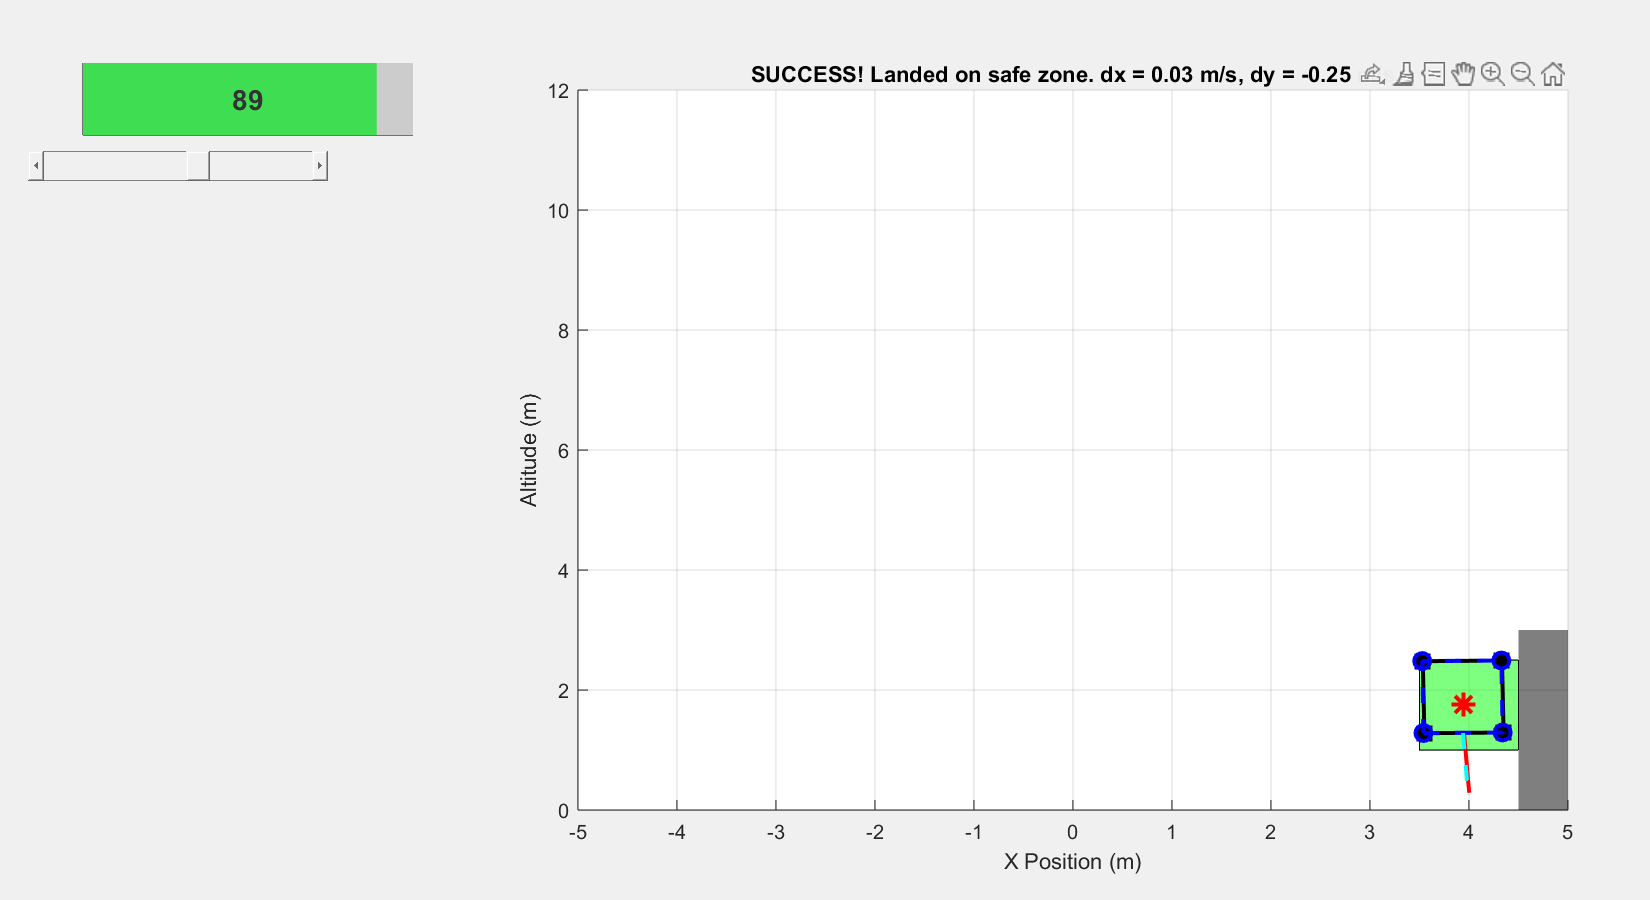

x_true = zeros(6,1);
x_true(3) = 12;   % Initial altitude = 12 m
x_true(4) = -2 + rand(1, 1);   % Initial vertical velocity

x_hat = x_true;

%% Setup figure, sliders, and plot handles
f = figure('Name', 'Lander Simulation with Observer, LQR & Gamification',...
    'NumberTitle','off','Position',[100 100 1100 600]);

score_bar_bg = axes('Parent', f, 'Position', [0.05 0.85 0.2 0.08], 'XTick', [], 'YTick', [], 'Color', [0.9 0.9 0.9]);
xlim(score_bar_bg, [0 100]);
ylim(score_bar_bg, [0 1]);
rectangle(score_bar_bg, 'Position', [0 0 100 1], 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');

% Add dynamic score bar (green to red gradient)
score_bar = patch(score_bar_bg, [0 100 100 0], [0 0 1 1], [0.2 0.8 0.2],...
    'EdgeColor', 'none', 'FaceAlpha', 0.8);

% Add score text overlay
score_text = text(score_bar_bg, 50, 0.5, '100',...
    'HorizontalAlignment', 'center', 'FontSize', 14,...
    'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);

% Add score label
text(score_bar_bg, 3000, 1.1, 'SCORE',...
    'HorizontalAlignment', 'center', 'FontSize', 10,...
    'FontWeight', 'bold', 'Color', [0.4 0.4 0.4]);

% Axes for the simulation plot
ax = axes('Position',[0.35 0.1 0.6 0.8]);
hold on; grid on;
xlabel('X Position (m)');
ylabel('Altitude (m)');
xlim([-5 5]); ylim([0 12]);
title('Lander: True (black) vs Estimated (blue) vs Reference (red star)');

% Draw the safe landing zone (green square)
safe_x = [safe_zone.x, safe_zone.x+safe_zone.width, safe_zone.x+safe_zone.width, safe_zone.x];
x_target = safe_zone.x + safe_zone.width/2 - 0.05;
safe_y = [safe_zone.y, safe_zone.y, safe_zone.y+safe_zone.height, safe_zone.y+safe_zone.height];
y_target = safe_zone.y + safe_zone.height/2;
h_safe = patch(safe_x, safe_y, 'g', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Draw the hazard zone (black tower)
hazard_x = [hazard_zone.x, hazard_zone.x+hazard_zone.width, hazard_zone.x+hazard_zone.width, hazard_zone.x];
hazard_y = [hazard_zone.y, hazard_zone.y, hazard_zone.y+hazard_zone.height, hazard_zone.y+hazard_zone.height];
h_hazard = patch(hazard_x, hazard_y, 'k', 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Create plot handles for lander bodies, nozzles, and reference marker
h_true        = plot(0,0, 'ks-', 'LineWidth',2, 'MarkerSize',8, 'MarkerFaceColor','k');
h_nozzle_true = plot(0,0, 'r-', 'LineWidth',2);
h_est         = plot(0,0, 'bo--', 'LineWidth',2, 'MarkerSize',8);
h_nozzle_est  = plot(0,0, 'c--', 'LineWidth',2);
h_ref         = plot(0,0, 'r*', 'MarkerSize',12, 'LineWidth',2);

uicontrol('Style','text','Position',[20 500 140 20],'String','Reference Altitude r_y (m)', 'visible', 'off');
r_y_slider = uicontrol('Style','slider','Min',0,'Max',12,'Value',7,...
    'Position',[20 480 200 20]);

%% Simulation loop
k = 1;
landed = false;
while ishandle(f) && k <= length(time)
    lambda = 0.2;  % Tune this based on system aggressiveness
    t = k * dt;
    r_x = x_target + (x_hat(1) - x_target) * exp(-lambda * t);
    r_y = y_target + (x_hat(3) - y_target) * exp(-lambda * t);

    % Form reference state: desired [x; dx; y; dy; theta; dtheta]
    x_ref = [r_x; 0; r_y; 0; 0; 0];
    
    % Compute LQR control based on the observer estimate:
    % u = u_eq - K_lqr*(x_hat - x_ref)
    u = lqrController(x_hat, x_ref, u_eq, K_lqr);
    
    % Update true state using the nonlinear dynamics
    x_true = updateTrueState(x_true, u, dt, m, I, g, l1);
    
    % Simulate measurement (with slight Gaussian noise)
    noise_level = [0.05; 0.05; 0.01];
    y_meas = C * x_true + noise_level .* randn(3,1);
    
    % Update observer using the linearized model
    x_hat = updateObserver(x_hat, u, y_meas, dt, A, B, C, L_obs);
    
    % Compute lander shapes for drawing (nozzle command is u(2); expected near zero)
    nozzle_command = u(2);
    [lander_x_true, lander_y_true, nozzle_x_true, nozzle_y_true] = computeLanderShape(x_true, lander_dims, nozzle_command);
    [lander_x_est,  lander_y_est,  nozzle_x_est,  nozzle_y_est]  = computeLanderShape(x_hat, lander_dims, nozzle_command);
    
    % Update plot handles for the true state
    set(h_true, 'XData', lander_x_true, 'YData', lander_y_true);
    set(h_nozzle_true, 'XData', nozzle_x_true, 'YData', nozzle_y_true);
    
    % Update plot handles for the estimated state
    set(h_est, 'XData', lander_x_est, 'YData', lander_y_est);
    set(h_nozzle_est, 'XData', nozzle_x_est, 'YData', nozzle_y_est);
    
    % Update reference marker
    set(h_ref, 'XData', r_x, 'YData', r_y);
    
    % Check landing conditions using the new function.
    [landed, success, vel] = checkLanding(x_true, lander_dims, safe_zone, hazard_zone);
    if landed
        if success
            result_str = sprintf('SUCCESS! Landed on safe zone. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        else
            result_str = sprintf('FAILURE! Crash landing. dx = %.2f m/s, dy = %.2f m/s', vel(1), vel(2));
        end
        title(ax, result_str);
        break;  % End simulation loop upon landing
    else
        % Update title with ongoing state info
        title(ax, sprintf('Altitude: True = %.2f m, Est = %.2f m, Ref = %.2f m | Theta: True = %.2f rad, Est = %.2f rad',...
            x_true(3), x_hat(3), r_y, x_true(5), x_hat(5)));
    end

    % Update score bar and text
    current_score = max(0, 100 - floor((k-1)*dt));
    score_ratio = current_score/100;
    
    % Update bar color (green to red gradient)
    set(score_bar,...
        'XData', [0 current_score current_score 0],...
        'FaceColor', [1-score_ratio, score_ratio, 0.2]);
    
    % Update text
    set(score_text, 'String', num2str(current_score));
    
    % Flash red when below 100
    if current_score < 10
        set(score_bar, 'FaceColor', [1 0 0]);
    end
    
    drawnow;
    pause(dt);
    k = k + 1;
end


if landed
    if success
        disp('Landing SUCCESS!');
    else
        disp('Landing FAILURE!');
    end
    fprintf('Final velocities: dx = %.2f m/s, dy = %.2f m/s\n', vel(1), vel(2));
else
    disp('Simulation ended without landing.');
end

Landing SUCCESS!


Final velocities: dx = 0.03 m/s, dy = -0.25 m/s
